bml_defaults

SUBJECT='EM1125';
SESSION = 'Lombard';
TASK = 'lombard';
PATH_DATASET = 'Y:\EMU';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];
PATH_FIELDTRIP = [PATH_DER_SUB filesep 'fieldtrip'];

PATH_FIG = [PATH_PREPROC '\figures'];

FNAME_BASE = ['sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_preproc']; 

% loading annotation tables
% sessions = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_sessions.tsv']);
runs = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_runs.tsv']);

% channels = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_channels.tsv']);
trials = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_annot-trials.tsv']);

runs_task = runs(runs.task == string(TASK), :);

## Define rejection parameters

CRITERIA = 'A';
chs_oi = {'all', '-OSAT', '-TRIG', '-PR', '-Pleth'}; % channels of interest


HIGH_PASS_FILTER = 'yes'; %should a high pass filter be applied
HIGH_PASS_FILTER_FREQ = 1; %cutoff frequency of high pass filter

ECOG_ENVELOPE_BIN_SIZE_SECONDS = 1; %envelope bin size in seconds
ECOG_THRESHOLD_STD_FACTORS = [2, 3]; %factors to determine detection thresholds 
ECOG_CONSOLIDATION_TIME_TOLERANCE = 3; %min time allowed between adjacent artifacts
ELECTRODE_COVERAGE_THRESHOLD = 0.5; % max allowed fraction of time with artifacts
CONNECTOR_THRESHOLD = [4, 8]; % detection threshold for faulty electrodes in connector

## Load continuous FieldTrip data

load([PATH_FIELDTRIP filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_ft-raw.mat'],'D');
n_trials = numel(D.trial);

## Remove nans

cfg=[];
cfg.value = 0;
cfg.remask_nan = true;
D_mask = bml_mask(cfg,D); % ERROR with istrue()

## high pass filtering

cfg=[];
cfg.hpfilter=HIGH_PASS_FILTER;	 % setting a high pass filter
cfg.hpfreq=HIGH_PASS_FILTER_FREQ; % 1Hz cutoff frequency	
cfg.hpfilttype='but';    		 % using butterworth filter
cfg.hpfiltord=5;         		 % of order 5
cfg.hpfiltdir='twopass'; 		 % two passes not to introduce time shift
cfg.channel=chs_oi; %include channels to filter
D_hpf = ft_preprocessing(cfg,D_mask);

> In fixsampleinfo (line 102)
In ft_datatype_raw (line 149)
In ft_checkdata (



%notch filtering
freqs=[60 120 180 240];
cfg=[];
cfg.hpfilter='yes';
cfg.hpfreq=1;
cfg.hpfilttype='but';
cfg.hpfiltord=5;
cfg.hpfiltdir='twopass';
cfg.bsfilter='yes';
cfg.bsfreq= [freqs-1; freqs+1]';
D_notch = ft_preprocessing(cfg,D_hpf);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 81 seconds


## Visualize with FieldTrip

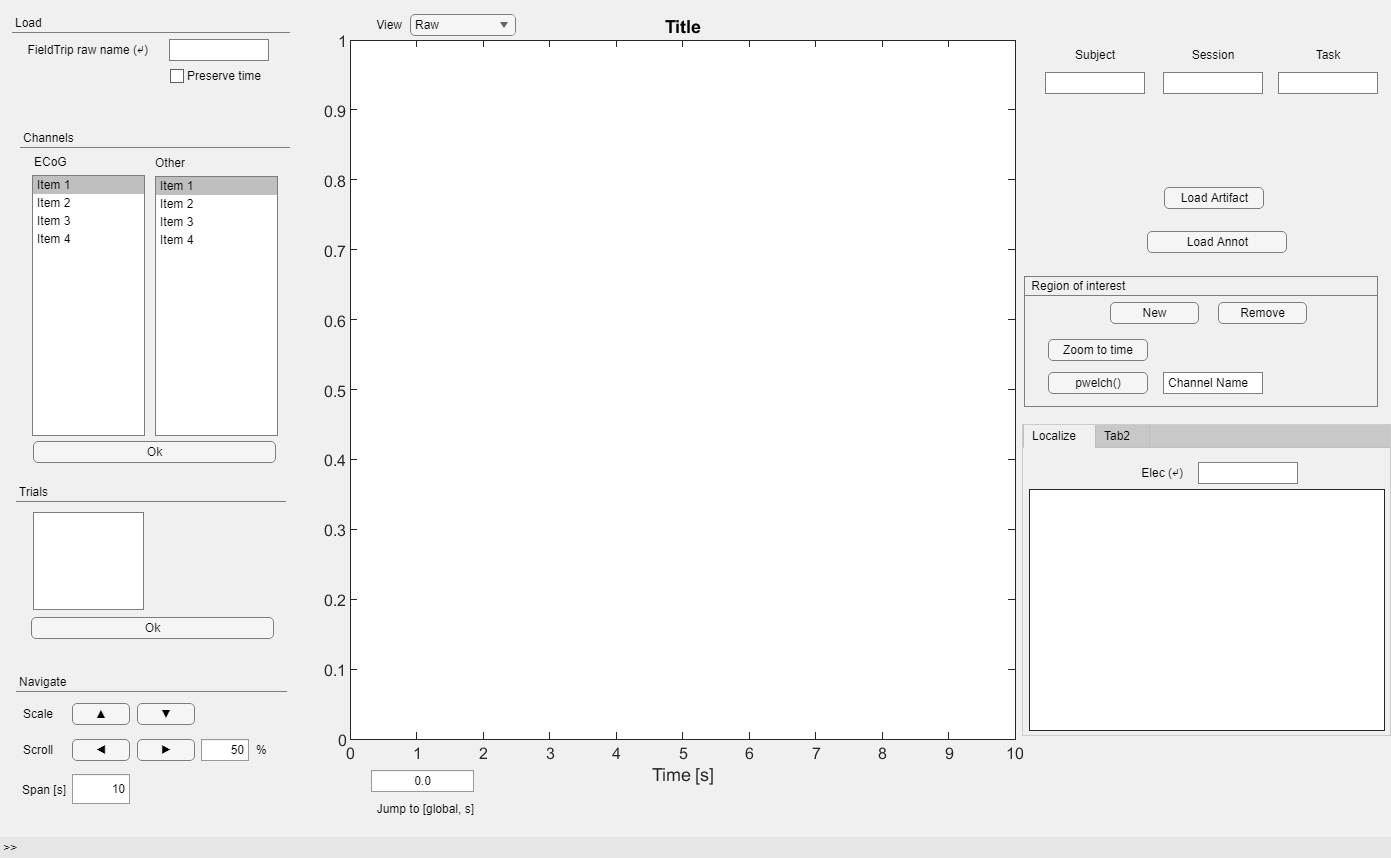

% cfg=[]; 
% cfg.channel = chs_oi{1}; 
% D_hpf_chsoi = ft_selectdata(cfg,D_hpf); % get channels of interest

D_hpf_chsoi = D_notch; 
bml_databrowser;

## Calculate envelopes

cfg=[];
cfg.freq=ECOG_ENVELOPE_BIN_SIZE_SECONDS;
D_hpf_chsoi_env = bml_envelope_binabs(cfg, D_hpf_chsoi);
D_hpf_chsoi_env_log10 = bml_apply(@(x) log10(x), D_hpf_chsoi_env);

## Determine thresholds

THRESHOLD = nan(n_trials,2);
for i=1:n_trials
  v = reshape(D_hpf_chsoi_env_log10.trial{i},1,[]);
  m = nanmedian(v);
  std = bml_robust_std(v);
  THRESHOLD(i,:) = m + ECOG_THRESHOLD_STD_FACTORS.*std;
end

## Visualize histogram

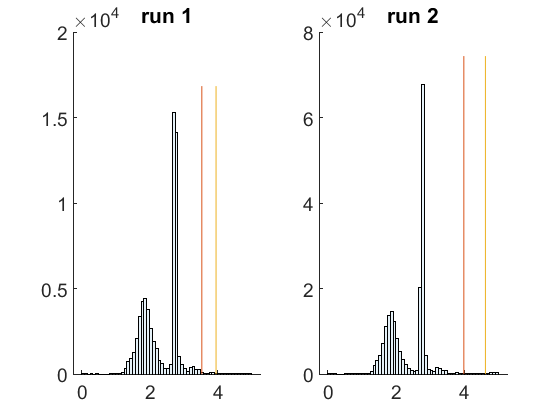

f=figure();
for i=1:n_trials
  subplot(ceil(n_trials/2),2,i)
  hold on;
  h=histogram(D_hpf_chsoi_env_log10.trial{i},linspace(0,5,61),...
'FaceAlpha',0.1,'EdgeAlpha',1);
  maxBinCount = max(h.BinCounts);
  plot([THRESHOLD(i,1),THRESHOLD(i,1)],[0,maxBinCount .* 1.1]);
  plot([THRESHOLD(i,2),THRESHOLD(i,2)],[0,maxBinCount .* 1.1]);
  title(['run ' num2str(i)]);
end

% saveas(f,['figures/' SUBJECT '_P08_ar_' CRITERIA '_hpf_ecog_env_log10_hist.png'])

## Detect segments of time for each channel above threshold, per session

artifact_chsoi_1 = table();
for i=1:n_trials
  cfg=[];
  cfg.threshold = THRESHOLD(i,:);
  cfg.trials = i;
  artifact_chsoi_1 = bml_annot_rowbind(artifact_chsoi_1,...
                                       bml_annot_detect(cfg,D_hpf_chsoi_env_log10));
end

Detecting trial 1, labels: 
LAMY1 LAMY2 LAMY3 LAMY4 LAMY5 LAMY6 LAMY7 LAMY8 LAMY9 LAMY10 
LAMY11 LAMY12 LAMY13 LAMY14 LH1 LH2 LH3 LH4 LH5 LH6 
LH7 LH8 LH9 LH10 LH11 LH12 LTSa1 LTSa2 LTSa3 LTSa4 
LTSa5 LTSa6 LTSa7 LTSa8 LFIa1 LFIa2 LFIa3 LFIa4 LFIa5 LFIa6 
LFIa7 LFIa8 LFIa9 LFIa10 LFIa11 LFIa12 LFIa13 LFIa14 LFIa15 LFIa16 
LFIb1 LFIb2 LFIb3 LFIb4 LFIb5 LFIb6 LFIb7 LFIb8 FP1 F7 
T3 T5 O1 F3 C3 P3 FP2 F8 T4 T6 
O2 F4 C4 P4 FZ C76 LFIc1 LFIc2 LFIc3 LFIc4 
LFIc5 LFIc6 LFIc7 LFIc8 LFIc9 LFIc10 LFIc11 LFIc12 LFIc13 LFIc14 
LFIc15 LFIc16 LPIa1 LPIa2 LPIa3 LPIa4 LPIa5 LPIa6 LPIa7 LPIa8 
LPIa9 LPIa10 LPIa11 LPIa12 LPIa13 LPIa14 LPIa15 LPIa16 LPIb1 LPIb2 
LPIb3 LPIb4 LPIb5 LPIb6 LPIb7 LPIb8 LPIb9 LPIb10 LPIb11 LPIb12 
LPIb13 LPIb14 LPIb15 LPIb16 CZ PZ T1 T2 LTSb1 LTSb2 
LTSb3 LTSb4 LTSb5 LTSb6 LTSb7 LTSb8 LTSb9 LTSb10 LTB1 LTB2 
LTB3 LTB4 LTB5 LTB6 LTB7 LTB8 LTB9 LTB10 LTB11 LTB12 
LOC ROC CII EKG EMG1 EMG2 C157 C158 C159 C160 
C161 C162 C163 C164 C165 C166 C167 C168 C169 C170 
C171 C172 C173 C17


artifact_chsoi_1 = renamevars(artifact_chsoi_1, 'label', 'ch_name');

% Consolidate instances within a certain time threshold of each other 
cfg=[];
cfg.criterion = @(x) (x.starts(end) - max(x.ends(1:(end-1))) < ECOG_CONSOLIDATION_TIME_TOLERANCE);
cfg.groupby = 'ch_name';
artifact_chsoi_2 = bml_annot_consolidate(cfg, artifact_chsoi_1);

## Visualize with raster plot

artifact_chsoi_3 = artifact_chsoi_2; 

cfg=[];
cfg.template = D_hpf_chsoi_env_log10;  	% ft_raw object to use as template
cfg.label_colname='ch_name';   		% what variable of the table to use as channel name 
artifact_chsoi_3_raw = bml_annot2raw(cfg, artifact_chsoi_3);

using labels from template


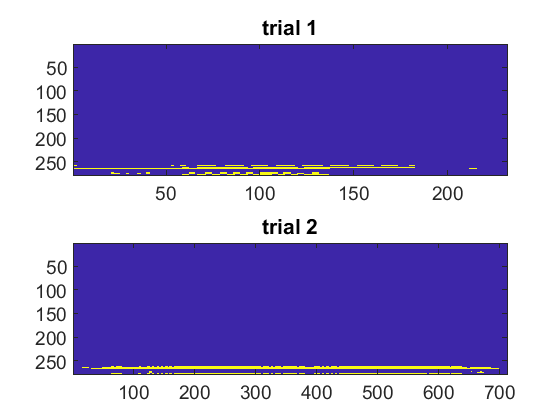


f=figure();
bml_plot_raster(artifact_chsoi_3_raw);

## Detect artifactual channels

Note: the function bml_annot_coverage implements a kind of "division" between annotation tables. For every row in session, it checks what fraction of that time interval coincides with rows in artifact_1. It does this grouping first by label, that means it will return one row per label per session. The returned object is an annotation table.

cfg = [];
cfg.groupby = 'ch_name';
artifact_1_session_cvg = bml_annot_coverage(cfg, artifact_chsoi_1, runs_task);

artifact_1_session_cvg_sel = artifact_1_session_cvg( ...
    artifact_1_session_cvg.coverage >= ELECTRODE_COVERAGE_THRESHOLD,:);

Reject selected "electrodes by sessions"

The easiest way of doing this, is combining the table 'artifact_1_session_cvg_sel ' with 'artifact_1' and then consolidating. Conceptually, we are making an union of both annotation tables, grouping by 'label'. 

cfg=[];
cfg.groupby = 'ch_name';
artifact_2 = bml_annot_union(cfg,artifact_chsoi_1, artifact_1_session_cvg_sel);

Make raster plot to visualize effect of rejecting entire electrode

%creating ft_raw from annotations for visualization
cfg=[];
cfg.template = D_hpf_chsoi_env;
cfg.label_colname='ch_name';
artifact2_raw = bml_annot2raw(cfg, artifact_2);

using labels from template


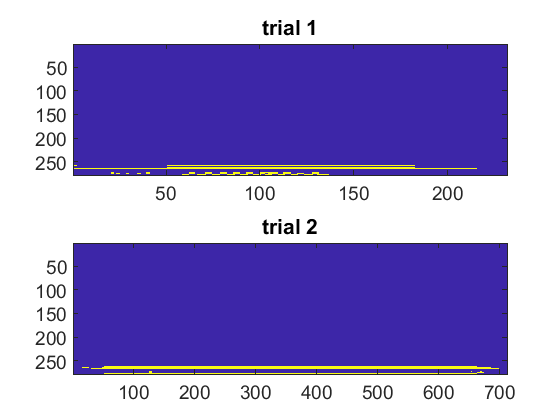


%raster plot of artifacts 
f=figure();
bml_plot_raster(artifact2_raw)

## Save annotation table

artifact = artifact_2(:,{'id','starts','ends','duration','ch_name','trial'});
artifact = renamevars(artifact, 'trial', 'run_id');
artifact = renamevars(artifact, 'ch_name', 'channel');
artifact.subject_id = repmat(SUBJECT, [height(artifact) 1]);
artifact.session_id = repmat(SESSION, [height(artifact) 1]);
artifact.task_id = repmat(TASK, [height(artifact) 1]);

bml_annot_write_tsv(artifact, [PATH_ANNOT filesep bml_bids_basefname(SUBJECT, SESSION, TASK) '_annot-artifact_criteria-' CRITERIA '.tsv']);
